# Matrix-Vector Multiplication (by rows)

function MatVec1(A, x, y)  (given at the end of this Live Script) implements the operation 


$$A x + y $$


computing by rows.   The below tests this function.

m = 4;
n = 3;

Create random $A$, $x$, and $y$.

A = randi( [ -3, 3 ], [ m, n ] )

A =      3     2     0
    -3     2     1
     0    -2     1
    -1     0     2


x = randi( [ -2, 2 ], [ n, 1 ] )

x =     -1
     1
     1


y = randi( [ -2, 2 ], [ m, 1 ] )

y =     -2
    -2
     0
     2


Compute $A x + y $ with function `MatVec1`

MatVec1( A, x, y )

ans =     -3
     4
    -1
     5


Compare result with that of Gemv_unb_var1:

if isequal( MatVec1( A, x, y ), Gemv_unb_var1( A, x, y ) )
    disp( 'All is well' );
else
    disp( 'Hmmm, something seems to be wrong' );
end

All is well


The function MatVec1( A, x, y ) follows below.  For reference, we give the algorithm for Variant 1:

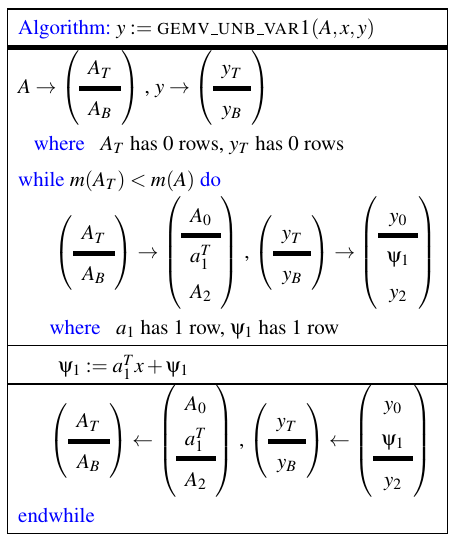

function [ y_out ] = MatVec1( A, x, y )
% Compute y := A x + y 

% Extract the row and column size of A
[ m, n ] = size( A );

% (Strictly speaking you should check that x is a vector size n and y is a
% vector of size m...)

% Copy y into y_out
y_out = y;

% Compute y_out = A * x + y_out
for i = 1:m
    for j=1:n
        y_out( i ) = A( i,j ) * x( j ) + y_out( i );
    end   
end

end

function [ y_out ] = Gemv_unb_var1( A, x, y )

  [ AT, ...
    AB ] = FLA_Part_2x1( A, ...
                         0, 'FLA_TOP' );

  [ yT, ...
    yB ] = FLA_Part_2x1( y, ...
                         0, 'FLA_TOP' );

  while ( size( AT, 1 ) < size( A, 1 ) )

    [ A0, ...
      a1t, ...
      A2 ] = FLA_Repart_2x1_to_3x1( AT, ...
                                    AB, ...
                                    1, 'FLA_BOTTOM' );

    [ y0, ...
      psi1, ...
      y2 ] = FLA_Repart_2x1_to_3x1( yT, ...
                                    yB, ...
                                    1, 'FLA_BOTTOM' );

    %------------------------------------------------------------%

    psi1 = a1t * x + psi1;

    %------------------------------------------------------------%

    [ AT, ...
      AB ] = FLA_Cont_with_3x1_to_2x1( A0, ...
                                       a1t, ...
                                       A2, ...
                                       'FLA_TOP' );

    [ yT, ...
      yB ] = FLA_Cont_with_3x1_to_2x1( y0, ...
                                       psi1, ...
                                       y2, ...
                                       'FLA_TOP' );

  end

  y_out = [ yT
            yB ];

end

